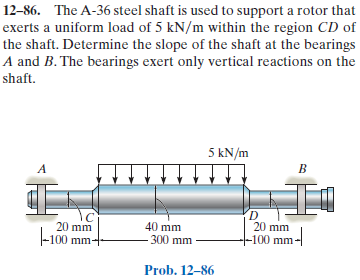

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-86P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-86P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 500*u.mm);
b = b.add('distributed', 'force', -5*u.kN/u.m, [100 400]*u.mm);
b.L = 500*u.mm;

# section properties

x = sym('x');
D(x) = piecewise(x <= 100*u.mm, 20*u.mm, ...
                 100*u.mm < x & x <= 400*u.mm, 40*u.mm, ...
                 x > 400*u.mm, 20*u.mm);
b.E = 200*u.GPa;
b.I = sympi*(D/2)^4/4;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y = rewrite(y, u.mm)

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(123000000\,{\mathrm{mm}}^{2}-3200\,x^{2}\right)}{12800000000\,\pi }\,\frac{1}{{\mathrm{mm}}^{2}} & \text{ if }x\leq 100\,\mathrm{mm}\\ -\frac{x^{4}-1000\,x^{3}\,\mathrm{mm}+60000\,x^{2}\,{\mathrm{mm}}^{2}+95000000\,x\,{\mathrm{mm}}^{3}+18100000000\,{\mathrm{mm}}^{4}}{38400000000\,\pi }\,\frac{1}{{\mathrm{mm}}^{3}} & \text{ if }x\in \left(100\,\mathrm{mm},400\,\mathrm{mm}\right]\\ -\frac{\left(x-500\,\mathrm{mm}\right)\,\left(2\,x^{2}-2000\,x\,\mathrm{mm}+423125\,{\mathrm{mm}}^{2}\right)}{8000000\,\pi }\,\frac{1}{{\mathrm{mm}}^{2}} & \text{ if }400\,\mathrm{mm}<x \end{array}\right.$$

dy = rewrite(dy, u.mm)

$$dy(x) = \left\{ \begin{array}{cl} -\frac{3\,\left(41000000\,{\mathrm{mm}}^{2}-3200\,x^{2}\right)}{12800000000\,\pi }\,\frac{1}{{\mathrm{mm}}^{2}} & \text{ if }x\leq 100\,\mathrm{mm}\\ \frac{\left(x-250\,\mathrm{mm}\right)\,\left(-x^{2}+500\,x\,\mathrm{mm}+95000\,{\mathrm{mm}}^{2}\right)}{9600000000\,\pi }\,\frac{1}{{\mathrm{mm}}^{3}} & \text{ if }x\in \left(100\,\mathrm{mm},400\,\mathrm{mm}\right]\\ -\frac{3\,\left(3200\,x^{2}-3200000\,x\,\mathrm{mm}+759000000\,{\mathrm{mm}}^{2}\right)}{12800000000\,\pi }\,\frac{1}{{\mathrm{mm}}^{2}} & \text{ if }400\,\mathrm{mm}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{3\,x}{4}\,\mathrm{kN} & \text{ if }x<100\,\mathrm{mm}\\ -\frac{x^{2}-500\,x\,\mathrm{mm}+10000\,{\mathrm{mm}}^{2}}{400}\,\frac{\mathrm{kN}}{\mathrm{mm}} & \text{ if }x\in \left[100\,\mathrm{mm},400\,\mathrm{mm}\right]\\ -\frac{3\,\left(x-500\,\mathrm{mm}\right)}{4}\,\mathrm{kN} & \text{ if }400\,\mathrm{mm}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{3}{4}\,\mathrm{kN} & \text{ if }x<100\,\mathrm{mm}\\ -\frac{x-250\,\mathrm{mm}}{200}\,\frac{\mathrm{kN}}{\mathrm{mm}} & \text{ if }x\in \left[100\,\mathrm{mm},400\,\mathrm{mm}\right]\\ -\frac{3}{4}\,\mathrm{kN} & \text{ if }400\,\mathrm{mm}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<100\,\mathrm{mm}\\ -5\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left[100\,\mathrm{mm},400\,\mathrm{mm}\right]\\ 0 & \text{ if }400\,\mathrm{mm}<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 0.75\,\mathrm{kN}\\ \mathrm{Rb} & 0.75\,\mathrm{kN} \end{array}\right)$$

ha_vpa = vpa(ha) %#ok<NASGU> 

 
ha_vpa =
 
Empty sym: 0-by-2
 


# shear and moment diagram

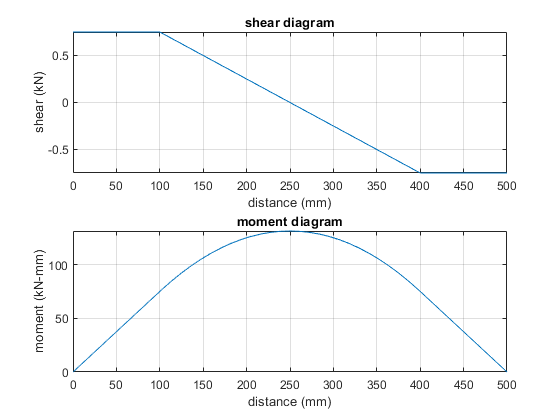

beam.shear_moment(m, v, [0 b.L], {'kN' 'mm'});

# slopes of the shafts at bearings A and B

dyA = rewrite(dy(0)*u.rad, u.deg);
dyA_vpa = vpa(dyA, 4) %#ok<NASGU> 

$$dyA\_vpa = -0.1753\,\deg$$

dyB = rewrite(dy(b.L)*u.rad, u.deg);
dyB_vpa = vpa(dyB, 4) %#ok<NASGU> 

$$dyB\_vpa = 0.1753\,\deg$$

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear ra_vpa ha_vpa;
clear dyA_vpa dyB_vpa;
clear old_assum;